## Input parameters

freqs = linspace(8.0e9, 8.1e9, 501);
res_freq = 8.05e9;
kappa_int = 3e6;
q_int = res_freq/kappa_int

q_int = 2.6833e+03

kappa_ext = 3e6;
q_ext = res_freq/kappa_ext

q_ext = 2.6833e+03

q_tot = (1/q_int + 1/q_ext)^(-1)

q_tot = 1.3417e+03

s21_transmission = 1 - (q_tot/q_ext)./(1 + 2*1i*q_tot.*(freqs - res_freq)/res_freq);
% s21_reflection = 1 - (q_tot/q_ext)./(1 + 1i*q_tot.*(freqs - res_freq)/res_freq);
[s21_reflection_real_cCPT, s21_reflection_imag_cCPT] = q_circle(freqs, kappa_int, kappa_ext, res_freq);

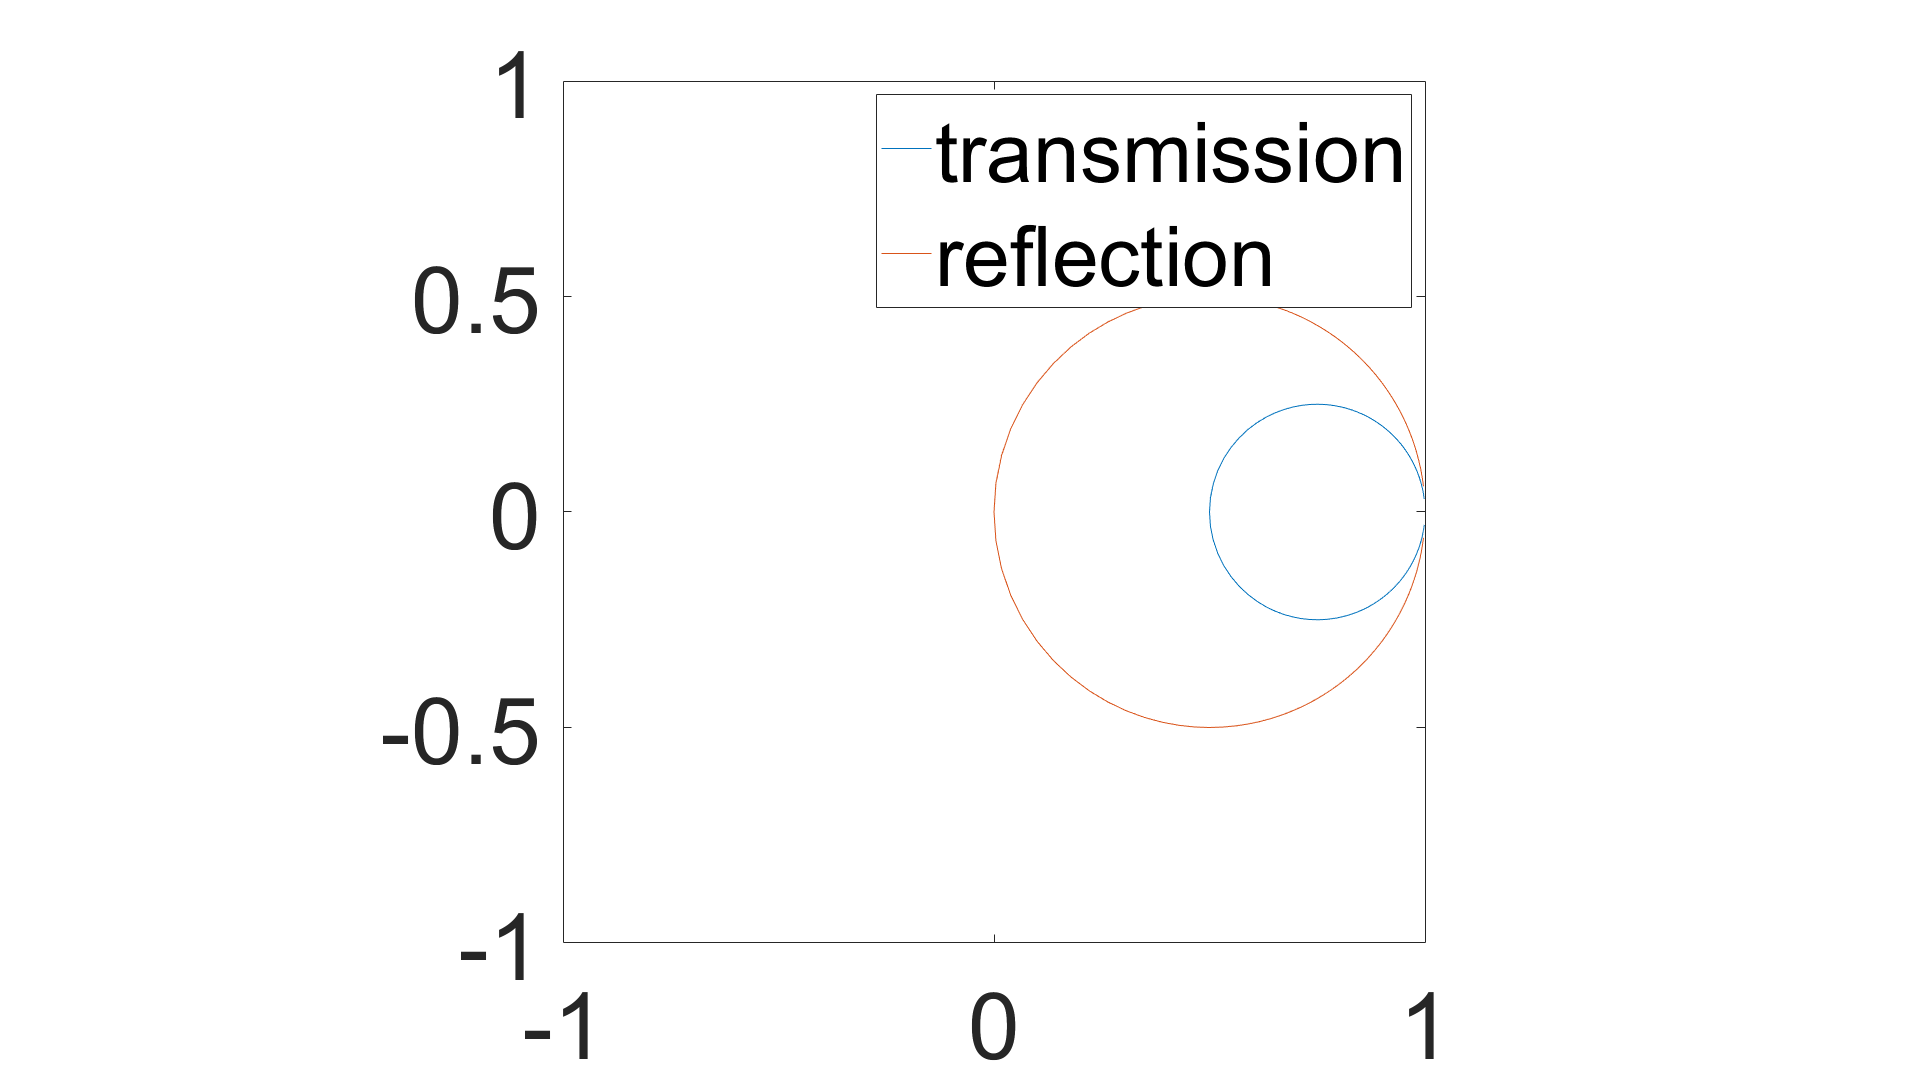

figure
plot(real(s21_transmission), imag(s21_transmission), 'DisplayName', 'transmission')
hold on
plot(s21_reflection_real_cCPT, s21_reflection_imag_cCPT, 'DisplayName', 'reflection')
legend show
daspect([1, 1, 1])
xlim([-1, 1])
ylim([-1, 1])

% plot(real(s21_reflection), imag(s21_reflection), 'x', 'MarkerSize',6)